# 遗传算法

本文件出自“从零开始学数学建模”课程；对应课程视频“5-4遗传算法”，获取课程链接请关注微信公众号：数学建模BOOM，回复“课程”

**问题**：现有**12份**快递需要配送，但一个快递员的**背包容量有限**，每份**快递的体积不同**、所能带来的**收益不同**，求解应该将哪些物品放进背包，能使得所选物品总体积不超过背包容量，且总收益最大？

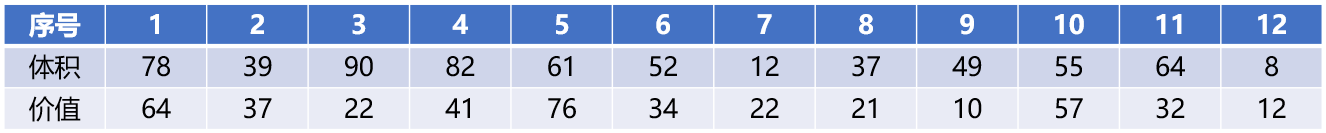

经典0-1背包问题，属于NP-Hard问题，暴力求解或动态规划在可选物品数量较多时都会带来指数级的时间复杂度，运行时间过长。此时可考虑启发式算法。

Np = 80;    % 种群个体数                        
N = 12;    % 物品数
V = 350;    % 背包容量  

Pc = 0.85;      % 交叉概率                  
Pv = 0.02;      % 变异概率
Gtime = 150;    % 遗传代数（迭代次数）                        
                           
C = [78,39,90,82,61,52,12,37,49,55,64,8];  % 物品体积
W = [64,37,22,41,76,34,22,21,10,57,32,12]; % 物品价值

alpha = 5;  % 惩罚系数

#### 基因编码

将变量转为二进制01的形式，以便于交叉和变异操作

对于1~12号快递，每个快递选中则设为1，不选则设为0，最终得到一组12位的0-1数组。例如[1,1,0,1,0,0,0,0,1,0,1,1]，意味着第1、2、4、9、11和12件快递被放入背包；

**初始化**：生成均匀分布的随机整数,Np行，N列，值为1表示选中该物品，0则不选

每一行就是一种选择方案，种群个体数Np为80，对应80种方案

population = randi([0,1],Np,N);     %随机获得初始种群

% 开始迭代
for t = 1:Gtime
    % 求每个个体的适应度
    for i = 1:Np
         fit(i) = fitness(population(i,:),C,W,V,alpha);
    end
    maxfit = max(fit);  % 适应度最大值（本轮迭代最优解的函数值）
    minfit = min(fit);
    
    % find函数找到满足等式的元素(最优个体)下标（在群体里的序号是几），可能有多个
    findex = find(fit == maxfit);
    fBest = population(findex(1,1),:);  % 根据序号选中最优个体

#### 轮盘赌法

累积概率表示每个个体之前所有个体的选择概率之和，相当于概率论中的概率分布函数F(x)。

轮盘赌法使得"**适应度越高的个体被选中的概率越大**"，且"**适应度低的个体仍有被选中的可能**"。详细讲解看本课程第三部分：“典型例题与原理讲解”

    fitvalue = fit ./ sum(fit);     % 被选中的概率，适应度越高的概率越大,累加为1

    fitvalue = cumsum(fitvalue);    % 累计概率。第i个元素，是原第1到i个元素之和
    bet = sort(rand(Np,1));         % 随机生成Np个（种群个体数）0到1的数并排序
    fit_i = 1;
    new_i = 1;
    while new_i <= Np
        % 排名第fit_i的个体，相应的累积概率大于轮盘中第new_i大的随机数时被选中
        if (fitvalue(fit_i)) > (bet(new_i))   
            %fprintf("选中第%d个个体,",fit_i)
            choosef(new_i,:) = population(fit_i,:);     % 该个体选中，赋值给choosef
            new_i = new_i + 1;  
            %fprintf("轮盘随机数变为%d;",new_i)
        else
            %fprintf("第%d个个体未被选中,",fit_i)
            fit_i = fit_i + 1;
            %fprintf("准备查看第%d个个体",fit_i)
        end
    end

**思考**：会不会出现fit_i大于80（数组population的元素个数）而带来语法错误？

轮盘赌法中的while循环，如果一直不满足if，随着fit_i不断增加，超过数组population的元素数量不就导致了语法错误么？如本题中fitvalue里有80个元素，如果fit_i增加到81怎么办？

**解答**：不会出现这种错误。因为fitvalue是累积概率，最后一项fitvalue(Np)=1；而bet里的元素都是大于0且小于1的随机数，因此fitvalue(80)=1>bet(80)；

所以while循环到最后，一定是new_i**先增大到大于Np**（本题Np=80）从而满足new_i <= Np，使得while循环结束，因此不会出现“fit_i超过80导致超出population数组下标的上限而报错”的情况。

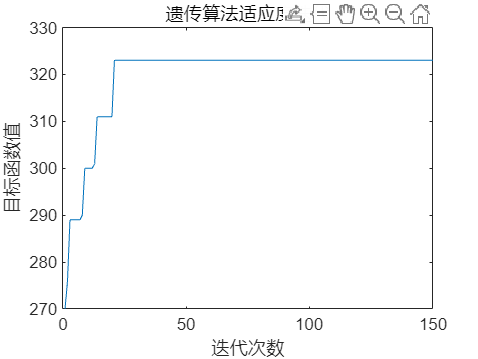

    % 交叉操作：第i个个体和第i+1个个体，进行第j位的基因互换
    for i = 1:2:Np  % 第1个和第2个个体，第3和第4个个体……两两交叉
        p = rand;   % 随机生成一个0到1之间的数，满足均匀分布
        if p < Pc   % 交叉概率Pc=0.85，及有85%的概率满足if语句
            q = randi([0,1],1,N);  % 生成1行Nt列的矩阵，其中元素随机是0或1
            for j = 1:N            % 对于12个物品基因（0或1），随机选中某些基因来进行交叉
                if q(j) == 1        % 随机生成的q中该位置元素为1，意味着第j个物品基因被选中进行交叉
                    temp = choosef(i + 1,j);            % 第i+1个个体的第j个基因赋值给临时变量
                    choosef(i + 1,j) = choosef(i,j);    % 第i个个体的第j个基因赋值给第i+1个个体
                    choosef(i,j) = temp;                % 同样，第i+1个个体的第j个基因复制给第i个个体，完成交叉
                end
            end
        end
    end

    % 变异操作
    for n = 1:Np        % 每个个体
        for m = 1:N     % 每个基因
            variation = rand(1,1);      % 生成一个大于0小于1的随机数
            if variation < Pv           % Pv=0.02，则有2%的概率满足if
                choosef(n,m) = ~choosef(n,m);   % 符号"~"是取反，0变1，1变0
            end
        end
    end
    population = choosef;       % 交叉和变异后的群体
    population(1,:) = fBest;    % 把交叉变异前的最优个体保留在群体首位
    trace(t) = maxfit;          % 本轮迭代的最优适应度
end
fBest;    % 迭代之后的最优个体
figure
plot(trace)
xlabel('迭代次数')
ylabel('目标函数值')
title('遗传算法适应度迭代')

function result = fitness(f,C,W,V,alpha)
fit = sum(f.*W);    % 当前方案总价值
TotalV = sum(f.*C); % 当前方案总体积
if TotalV > V
    fit = fit - alpha * (TotalV - V);   % 该方案所选的物品超过了背包总体积
end
result = fit;
end